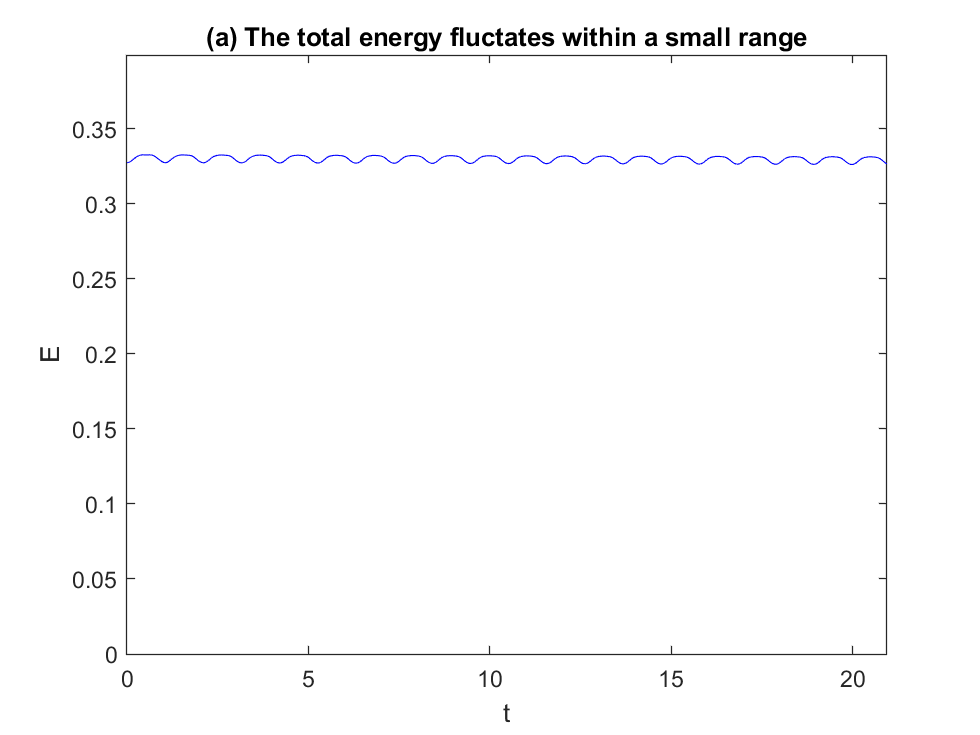

theta0 = 0.25;
thetad0 = 0;
g = 9.81;
omega2 = 9;
R = g/omega2;

[t, w] = pendulum_sin(R, theta0, thetad0, 0);
% t, x, v
K = 0.5*R^2*w(:, 2).^2;
U = 0.5*omega2*R^2*sin(w(:,1)).^2;
E = K + U;
figure
plot(t, E,'b-')
hold on
xlim([0 t(end)])
ylim([0 max(E)*1.2])
xlabel('t')
ylabel('E')
title('(a) The total energy fluctates within a small range')

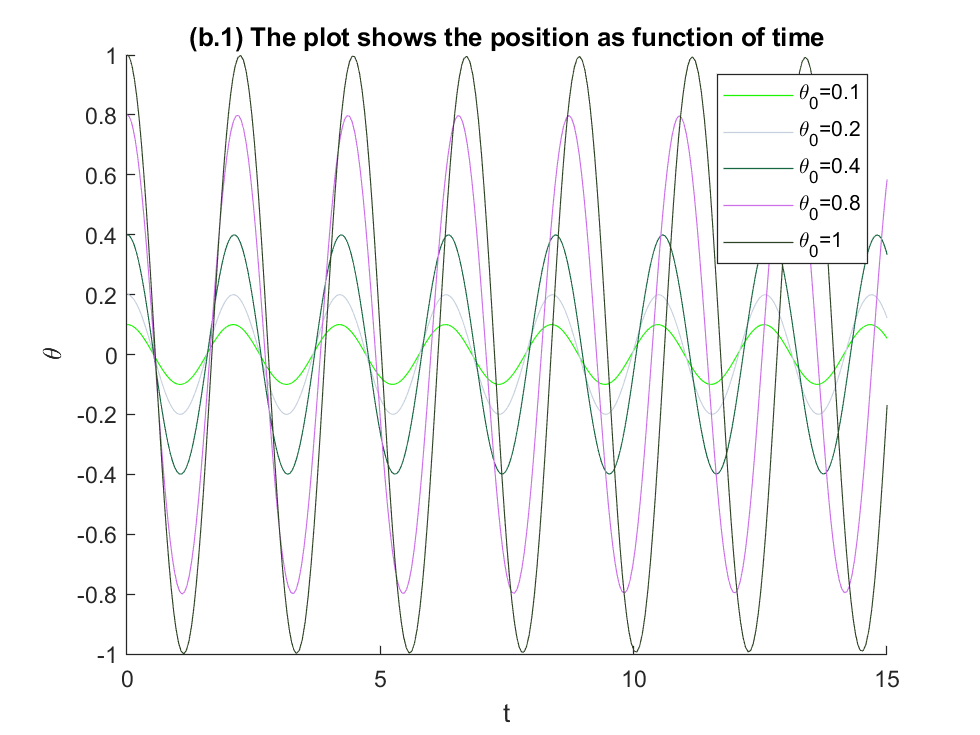

figure
hold on
for theta0=[0.1 0.2 0.4 0.8 1]
    thetad0 = 0;
    [t,w]=pendulum_sin(R, theta0, thetad0);
    plot(t, w(:,1), 'Color', rand(1, 3))
    
end
xlim([0 15])
xlabel('t')
ylabel('$\theta$','interpreter','latex')
legend('\theta_{0}=0.1','\theta_{0}=0.2','\theta_{0}=0.4', ...
    '\theta_{0}=0.8','\theta_{0}=1')
title('(b.1) The plot shows the position as function of time')

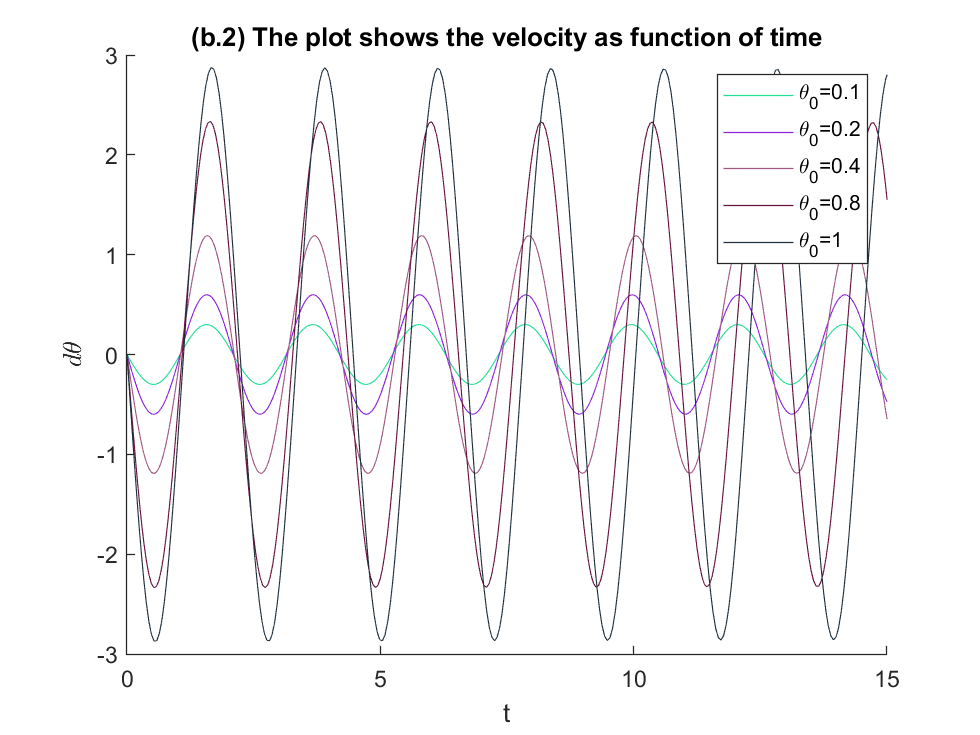

figure
hold on
for theta0=[0.1 0.2 0.4 0.8 1]
    thetad0 = 0;
    [t,w]=pendulum_sin(R, theta0, thetad0);
    plot(t, w(:,2), 'Color', rand(1, 3))
    
end
xlim([0 15])
xlabel('t')
ylabel('$d \theta$','interpreter','latex')
legend('\theta_{0}=0.1','\theta_{0}=0.2','\theta_{0}=0.4', ...
    '\theta_{0}=0.8','\theta_{0}=1')
title(['(b.2) The plot shows the velocity as function of time'])

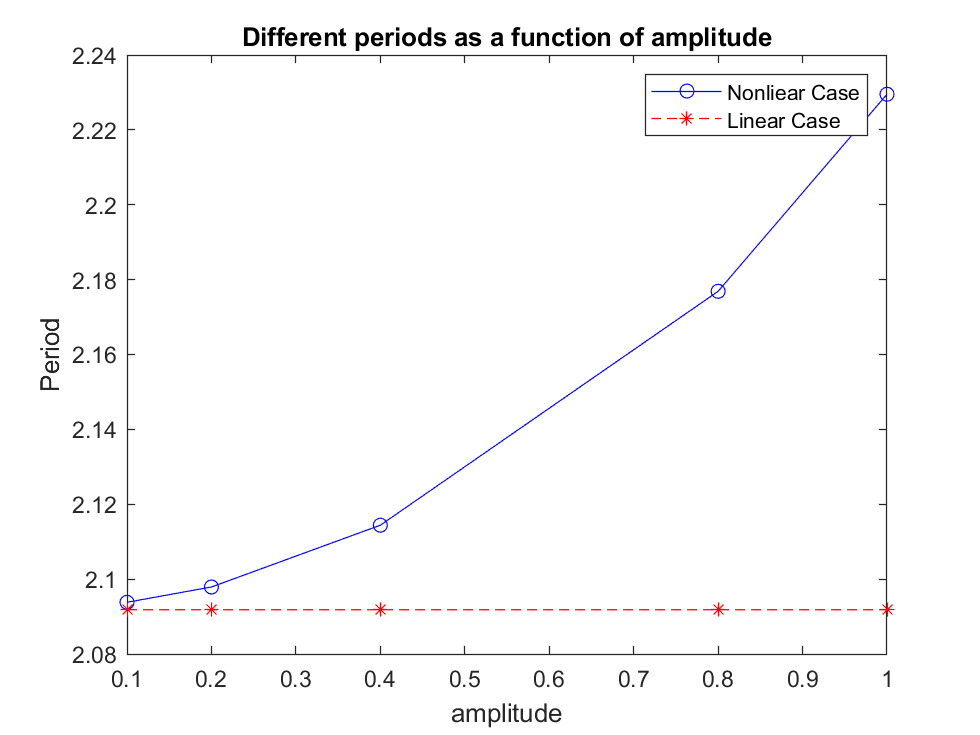

figure
i=0;
for theta0=[0.1 0.2 0.4 0.8 1]
    i = i+1;
    [t1,w1] = pendulum_sin(R,theta0,thetad0);
    [t2,w2] = pendulum(R,theta0,thetad0);
    A1(i) = max(w1(:,1));
    ind1 = find(w1(:,2).*circshift(w1(:,2), [-1 0]) <= 0);
    T1(i) = 2*mean(diff(t1(ind1(1:end-1))));
    ind1 = zeros;
    A2(i) = max(w2(:,1));
    ind2 = find(w2(:,2).*circshift(w2(:,2), [-1 0]) <= 0);
    T2(i) = 2*mean(diff(t2(ind2(1:end-1))));
    ind2 = zeros;
end
plot(A1, T1, 'bo-', A2, T2, 'r*--')
xlabel('amplitude')
ylabel('Period')
title('Different periods as a function of amplitude')
legend('Nonliear Case','Linear Case')

(b.3) The theta and delta theta deviate from standard sine wave in nonlinear case, but sine waves would work as an approximation.

As the amplitude (or energy, or  initial angle) increases, the period also 

In the linear case , the period is independent of the amplitude, so it is shorter than nonlinard case.

Physical explanation: at large angle, linear method gives bigger acceleration than the real value, so the period is shorter.